A = readtable("data1.csv");

A1= table2array(A1);
X = A1(:,1:5);
Y = A1(:,6);

PART1: ROP预测

对比模型：

随机森林，BP神经网络，单神经网络，基于遗传算法优化的BP神经网络预测，基于粒子群优化的BP神经网络预测

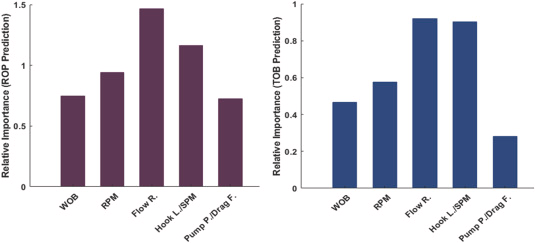

对于相关钻井特征参数对ROP的关键性评价

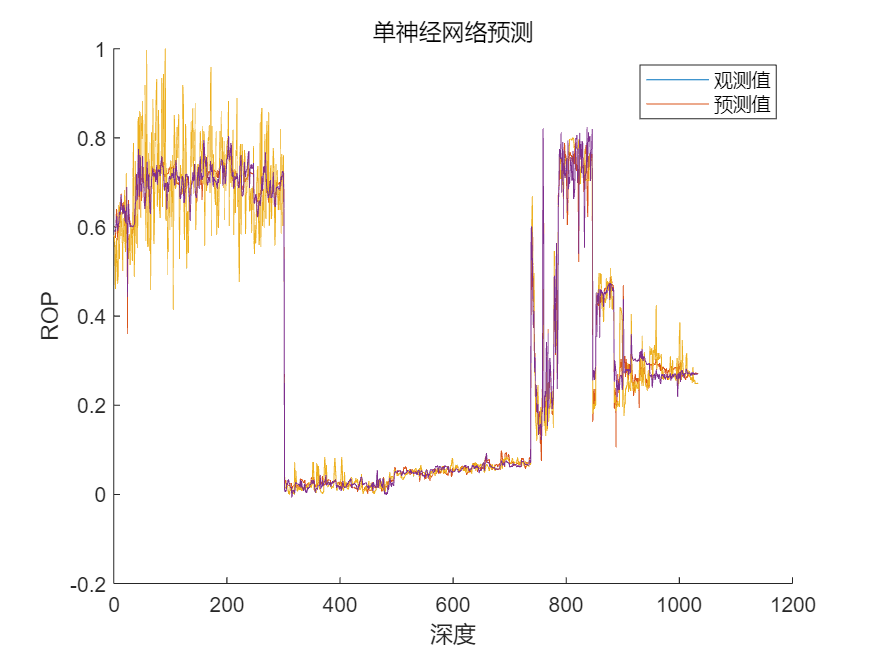


%BP神经网络
net = BPtrainedmodel.Network;
Y = table2array(A1(:,6));
A1= table2array(A1);
predict_y = zeros(1033,1); % 初始化predict_y
for i = 1: 1033
    result = sim(net, A1(i,1:5)');
    predict_y(i) = result;
end
%R = corrcoef(Y,predict_y);R = R(1,2);
figure(1)
hold on
plot(Y)
plot(predict_y)

legend('观测值','预测值')
title('BP神经网络预测')
xlabel('深度')
ylabel('ROP')

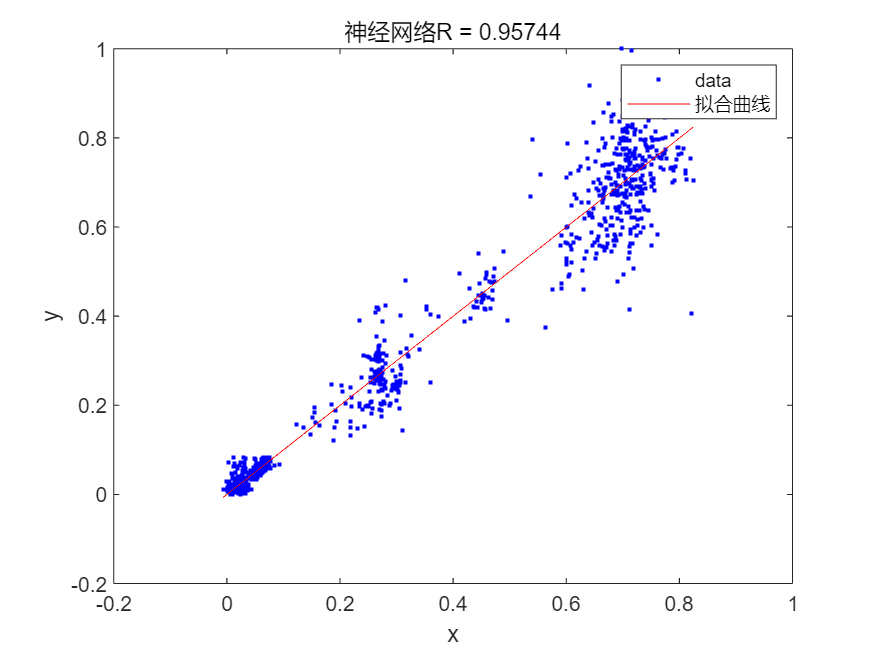


[fitresult.train, gof.train] = fit( predict_y, Y, 'poly1' );
R = gof.train.rsquare;


figure(2)
plot(fitresult.train,predict_y,Y)

title(['神经网络R = ' num2str(R)])

RF_MSE = errperf(Y,predict_y,'mse')

0.039

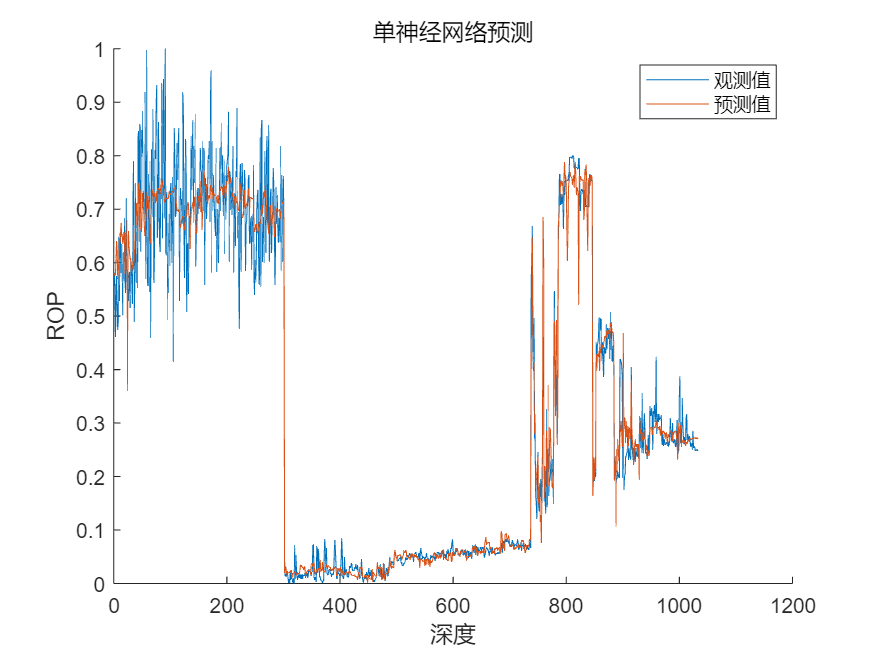

%单神经网络
Y = table2array(A1(:,6));
predict_y = zeros(1033,1); % 初始化predict_y
for i = 1: 1033
    result = nntrainedModel.predictFcn((A1(i,1:5)));
    predict_y(i) = result;
end
%R = corrcoef(Y,predict_y);R = R(1,2);
figure(1)
hold on
plot(Y)
plot(predict_y)

legend('观测值','预测值')
title('单神经网络预测')
xlabel('深度')
ylabel('ROP')

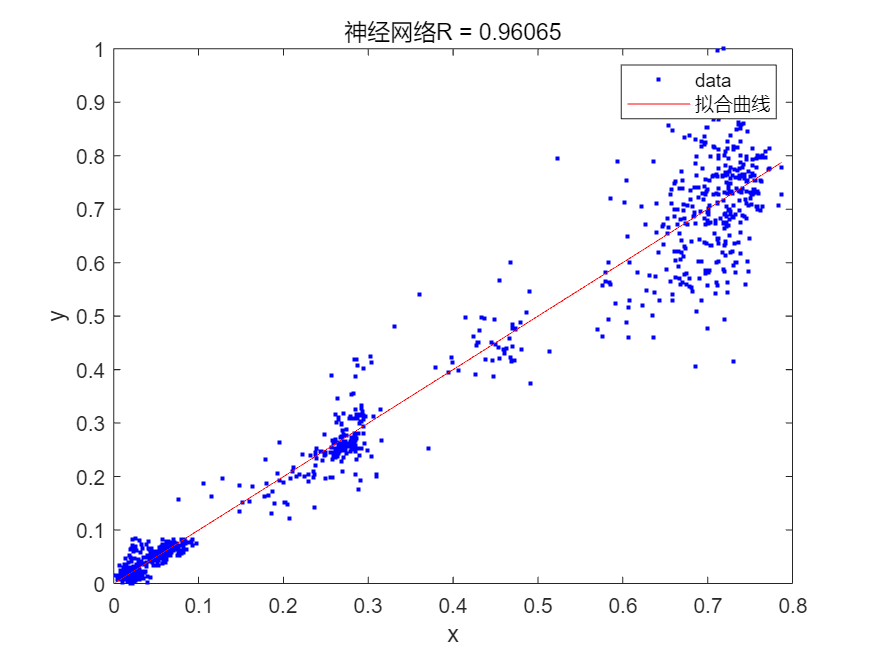



[fitresult.train, gof.train] = fit( predict_y, Y, 'poly1' );
R = gof.train.rsquare;


figure(2)
plot(fitresult.train,predict_y,Y)

title(['神经网络R = ' num2str(R)])


RF_MSE = errperf(Y,predict_y,'mse')

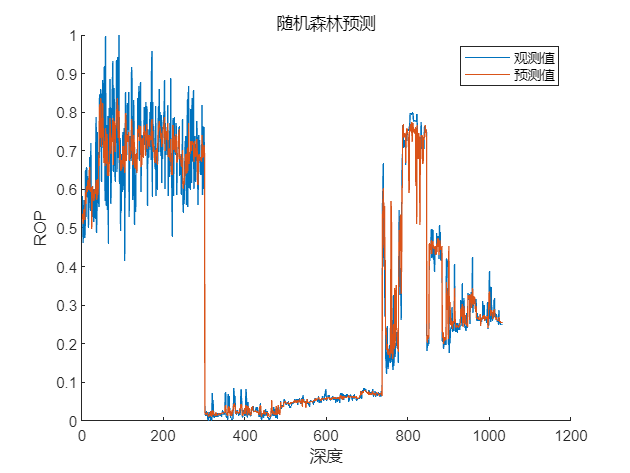


%%随机森林
predict_y = zeros(1033,1); % 初始化predict_y
for i = 1: 1033
    result = rftrainedModel.predictFcn((A1(i,1:5)));
    predict_y(i) = result;
end
R = corrcoef(Y,predict_y);
R = R(1,2);
figure
hold on
plot(Y)
plot(predict_y)

legend('观测值','预测值')
title('随机森林预测')
xlabel('深度')
ylabel('ROP')

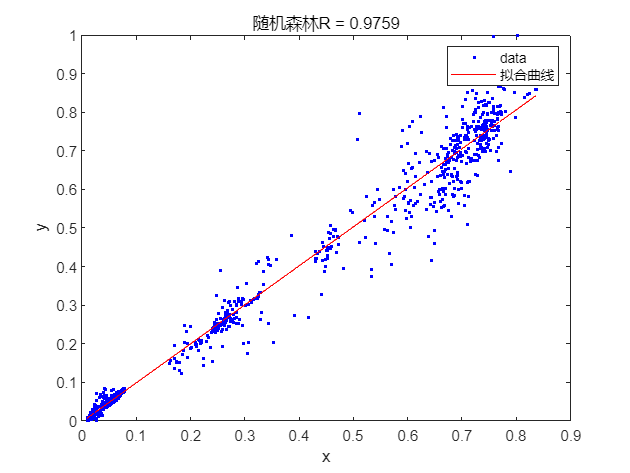


[fitresult.train, gof.train] = fit( predict_y, Y, 'poly1' );
R = gof.train.rsquare;

figure
plot(fitresult.train,predict_y,Y)
hold on
title(['随机森林R = ' num2str(R)])

RF_MSE = errperf(Y,predict_y,'mse')

RF_MSE = 0.0022

对于相关钻井特征参数对ROP的关键性评价

%%PART2：优化部分